% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 40);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "time_normalized", "TrunkAngle", "HipAngle", "KneeAngle", "AnkleAngle", "Red1_Raw_0_X", "Red1_Raw_0_Y", "Green_Raw_0_X", "Green_Raw_0_Y", "Blue1_Raw_0_X", "Blue1_Raw_0_Y", "Red2_Raw_0_X", "Red2_Raw_0_Y", "Blue2_Raw_0_X", "Blue2_Raw_0_Y", "MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"], "EmptyFieldRule", "auto");

% Import the data
Ansah1_1 = readtable("D:\2023 Project\6\c1\selected\Ansah1.1\Ansah1.1.csv", opts);

% Clear temporary variables
clear opts

% Display results
Ansah1_1

Ansah1_1 = 50×40 table
     time     time_normalized    TrunkAngle    HipAngle    KneeAngle    AnkleAngle    Red1_Raw_0_X    Red1_Raw_0_Y    Green_Raw_0_X    Green_Raw_0_Y    Blue1_Raw_0_X    Blue1_Raw_0_Y    Red2_Raw_0_X    Red2_Raw_0_Y    Blue2_Raw_0_X    Blue2_Raw_0_Y    MOI_InitialContact    MOI_InitialContact_ScoreValue    MOI_InitialContact_ScoreText    MOI_LoadingResponse    MOI_LoadingResponse_ScoreValue    MOI_LoadingResponse_ScoreText    MOI_MidStance    MOI_MidStance_ScoreValue    MOI_MidStance_ScoreText    MOI_TerminalStance    MOI_

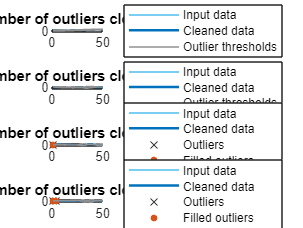

% Fill outliers
[newAnsah1_1,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(Ansah1_1(:,["time_normalized","HipAngle","KneeAngle","AnkleAngle"]),...
    "linear","movmedian",12);

% Display results
f = figure("Units","Normalized");
dv = [2 4 5 6];
N = numel(dv);
f.Position = [0 0 1 N/3];
tiledlayout(N,1,"Padding","compact");
for k = 1:N
    nexttile
    plot(Ansah1_1.(dv(k)),"Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(newAnsah1_1.(k),"Color",[0 114 189]/255,"LineWidth",1.5,...
        "DisplayName","Cleaned data")

    % Plot outliers
    plot(find(outlierIndices(:,k)),Ansah1_1.(dv(k))(outlierIndices(:,k)),"x",...
        "Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(find(outlierIndices(:,k)),newAnsah1_1.(k)(outlierIndices(:,k)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([(1:numel(Ansah1_1.(dv(k))))'; missing; (1:numel(Ansah1_1.(dv(k))))'],...
        [thresholdHigh.(k)(:); missing; thresholdLow.(k)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k)))
    legend("Location","EastOutside")
    ylabel(Ansah1_1.Properties.VariableNames{dv(k)},"Interpreter","none")
end

f.NextPlot = "new";
clear thresholdLow thresholdHigh f dv N k

## `Normalize`

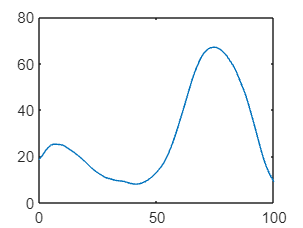

x=newAnsah1_1.time_normalized;
y=newAnsah1_1.KneeAngle;
i=0:1:100;
s = spline(x,y,i);
figure
plot(0:100,s)

## `Smoothening`

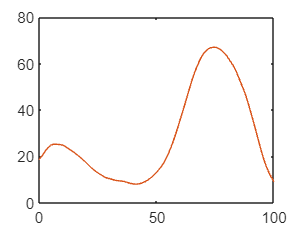

u = smooth(0:100, s, 0.01, 'rloess'); hold on;
plot(0:100,u)

v=diff(u)./diff(0:100);
a=diff(v)./diff(0:100);